# Plot each Spectrogram to look for artifacts

## Set Parameters for Chronux Spectrogram

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 50]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 
params.err = [2 0.05]

params = struct with fields:
        Fs: 1000
     fpass: [0 50]
       pad: 0
    tapers: [5 9]
       err: [2 0.0500]


##  Load and Plot Each Dataset

% Load each unhabituated trial for each
controls = {CT1, CT2, CT3, CT4, CT5, CT6, CT7, CT8}

controls = 1×8 cell array
    {1893260×2 single}    {3726858×2 single}    {3716176×2 single}    {3675772×2 single}    {3640352×2 single}    {3615364×2 single}    {3715866×2 single}    {3653016×2 single}


knockouts = {KO1, KO2, KO3, KO4, KO5, KO6, KO7, KO8}

knockouts = 1×8 cell array
    {1890190×2 single}    {3689071×2 single}    {3517539×2 single}    {3770358×2 single}    {3691845×2 single}    {3938323×2 single}    {3639901×2 single}    {3861380×2 single}



%{
for ii = 1:length(controls)
    disp('CONTROL')
    disp(ii)
    plot_spectrum_seg(controls{ii}, 10, params)
    plot_spectrogram(controls{ii}, [20 1], params)
    figure; plot (controls{ii}(:,1))
    disp('__________________________________________________________________________________')
end


for ii = 1:length(knockouts)
    disp("KNOCKOUT")
    disp(ii)
    plot_spectrum_seg(knockouts{ii}, 10, params)
    plot_spectrogram(knockouts{ii}, [20 1], params)
    figure; plot (knockouts{ii}(:,1))
    disp('______________________________________________________________________________________ ')
end
%}

## Vertically Concatenate Datasets

CTL_cat = vertcat_cell_array(controls);

x = 1893260×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 5620118×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 9336294×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 13012066×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 16652418×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 20267782×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 23983648×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 27636664×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


result = 27636664×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


KO_cat = vertcat_cell_array(knockouts);

x = 1890190×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 5579261×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 9096800×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 12867158×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 16559003×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 20497326×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 24137227×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 27998607×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


result = 27998607×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


# Remove Artifacts

In this section I remove artifacts from the data by filtering all signal beyond a modular limit (here limit = 0.5 mV) 

## Set Limit in mV

% Set limit 
limit = 0.5

limit = 0.5000

## Remove Artifacts 

% Filter 
CTL_cat_filter = artifact_filter(CTL_cat, limit)

result = 27520957×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


CTL_cat_filter = 27520957×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


KO_cat_filter = artifact_filter (KO_cat, limit)

result = 27789344×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


KO_cat_filter = 27789344×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


## Plot Raw Trace Before & After Artifact Filter

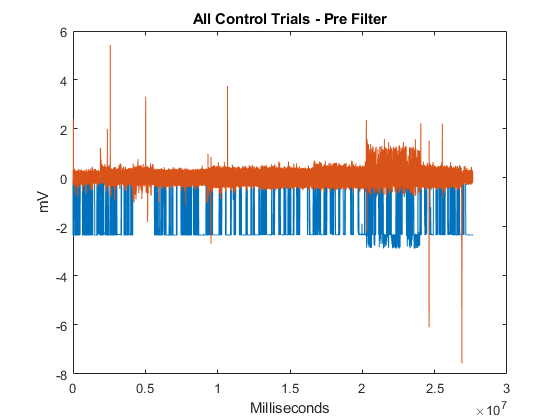

% Plot Artifact Unfiltered

figure; plot (CTL_cat); title('All Control Trials - Pre Filter'); xlabel('Milliseconds'); ylabel('mV');

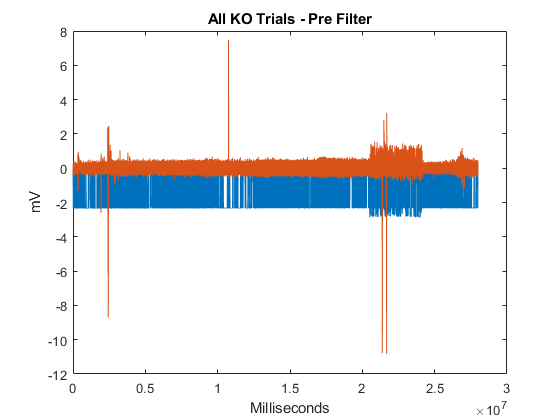

figure; plot (KO_cat); title('All KO Trials - Pre Filter'); xlabel('Milliseconds'); ylabel('mV');

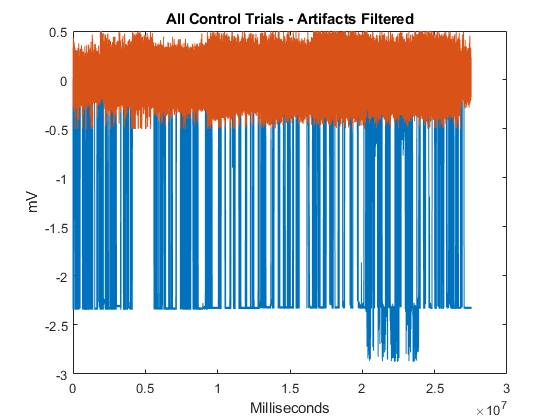


% Plot Artifact Filtered
figure; plot(CTL_cat_filter); title('All Control Trials - Artifacts Filtered'); xlabel('Milliseconds'); ylabel('mV');

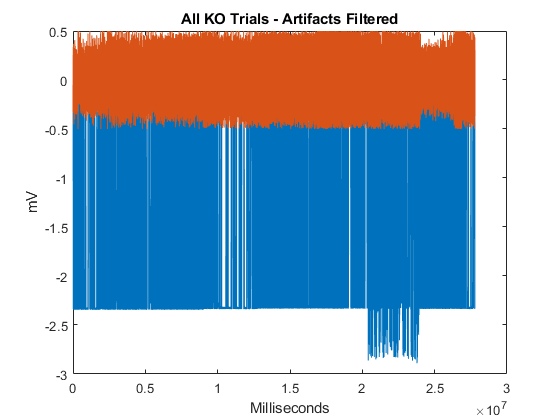

figure; plot(KO_cat_filter); title('All KO Trials - Artifacts Filtered'); xlabel('Milliseconds'); ylabel('mV');

## Plot Spectrogram Before & After Artifact Filter

%Set movingwin ([Seconds Step_Size])
movingwin = [20 1]

movingwin =     20     1


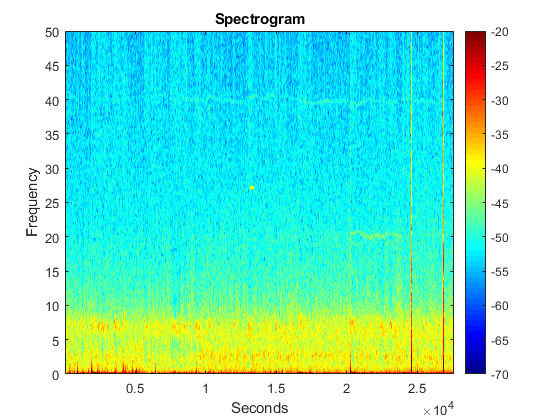


% Plot Artifact Unfiltered
plot_spectrogram(CTL_cat, movingwin, params)

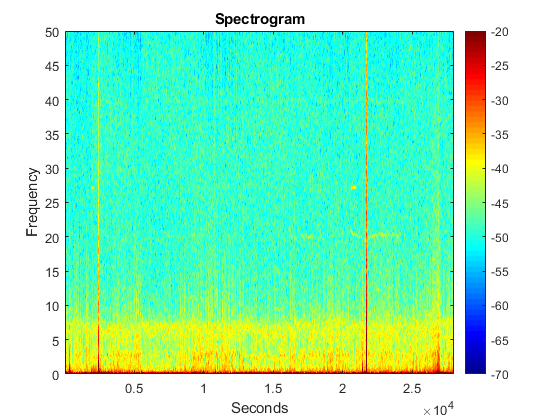

plot_spectrogram(KO_cat, movingwin, params)

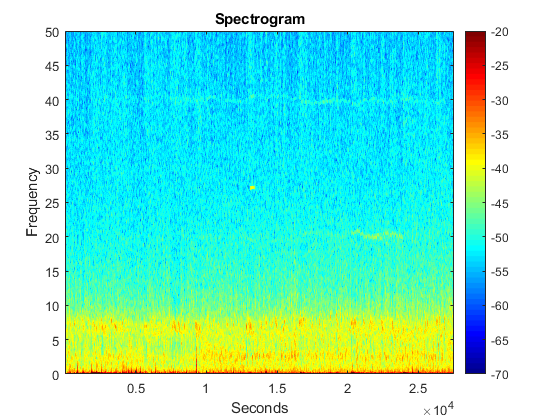


% Plot Artifact Filtered
plot_spectrogram(CTL_cat_filter, movingwin, params)

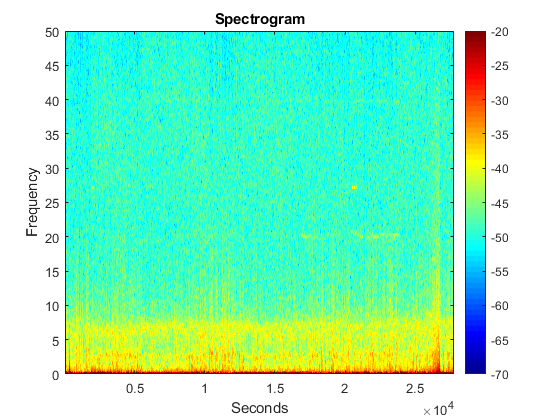

plot_spectrogram(KO_cat_filter, movingwin, params)

## Plot Spectrum_Seg20 Before & After Artifact Filter 

% Set Window to average over (seconds)
win = 20

win = 20


% Plot Artifact Unfiltered 
plot_spectrum_seg(CTL_cat, win, params)
plot_spectrum_seg(KO_cat, win, params)

% Plot Artifact Filtered
plot_spectrum_seg(CTL_cat_filter, win, params)
plot_spectrum_seg(KO_cat_filter, win, params)


%ending here 10PM 4/30

## Plot Spectrum Segs Together

win = 20

win = 20

params.fpass = [0 100]

params = struct with fields:
        Fs: 1000
     fpass: [0 100]
       pad: 0
    tapers: [5 9]
       err: [2 0.0500]


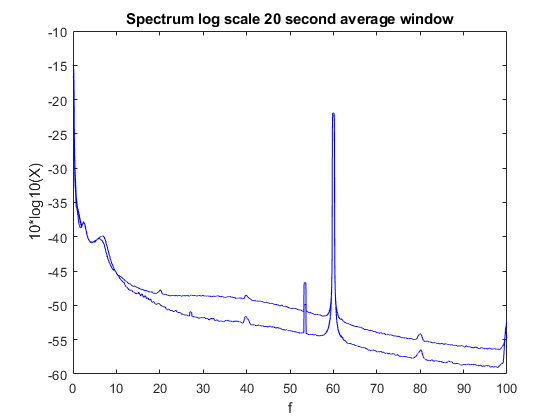

result = 1×2 cell array
    {1×3 cell}    {1×3 cell}


ans = 1×2 cell array
    {1×3 cell}    {1×3 cell}


plot_spectrum_seg_t(CTL_cat, KO_cat, win, params)

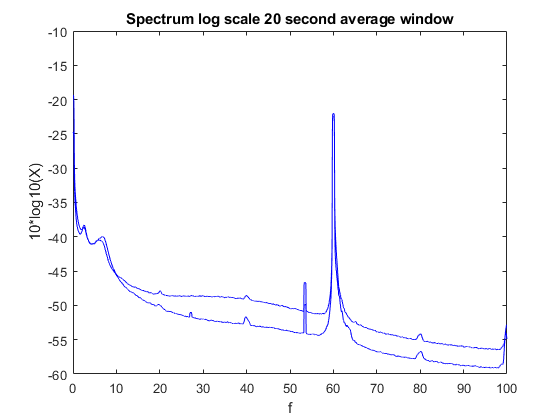

result = 1×2 cell array
    {1×3 cell}    {1×3 cell}


ans = 1×2 cell array
    {1×3 cell}    {1×3 cell}




plot_spectrum_seg_t(CTL_cat_filter, KO_cat_filter, win, params)

# Functions

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1}
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii}) 
end
result = x
end

## Calulate and Plot Spectrum over Average Window

function result = plot_spectrum_seg(arrayx, window, params)

% window is length in seconds to average over
segave = 1 ;
[S,f, Serr]=mtspectrumsegc(arrayx(:,2),window,params,segave);
figure; plot_vector(S,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
result = {S,f, Serr}
end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[S2, t2, f2] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(S2,t2,f2); colorbar; colormap jet; caxis ([-70 -20]); xlabel('Seconds'); ylabel('Frequency');

end

## Calculate and Plot Spectrum Segs Together

function result = plot_spectrum_seg_t (arrayx, arrayz, window, params)

% window is length in seconds to average over
segave = 1 ;

% Calculate 
[S1,f1, Serr1]=mtspectrumsegc(arrayx(:,2),window,params,segave);

[S2,f2, Serr2]=mtspectrumsegc(arrayz(:,2),window,params,segave);


% Plot
figure; plot_vector(S1,f1, 'l', Serr1); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
hold on 
plot_vector(S2,f2, 'l', Serr2)

result = {{S1,f1, Serr1}, {S2 f2 Serr2}}
end

## Filter out Artifacts (Array)

function result = artifact_filter(array, limit)

array(abs(array(:,2)) >= limit, :) = [];

result = array
end